# **PF**

## GLOBULOS BLANCOS

### a) Anotaciones

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\TF1N_1522'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.jpg'));

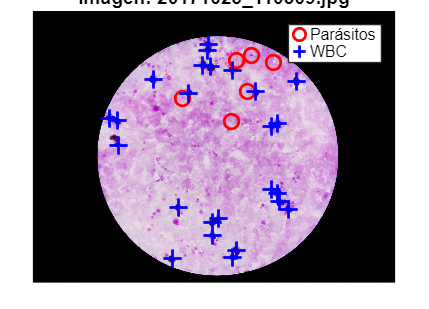

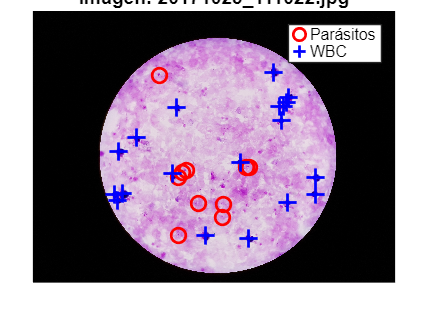

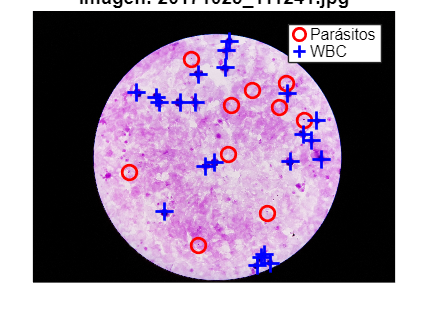

No se encontraron coordenadas de parásitos en la imagen: 20171023_111357.jpg


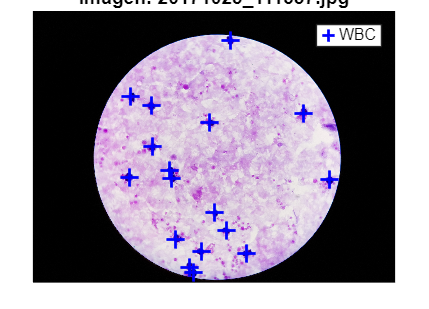

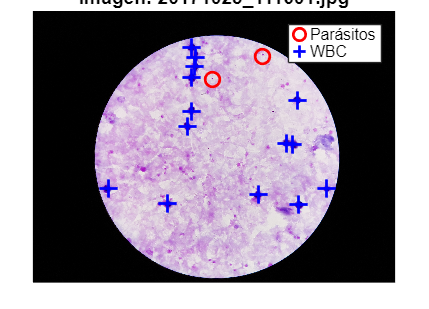

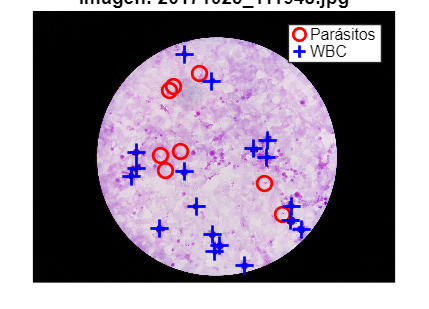

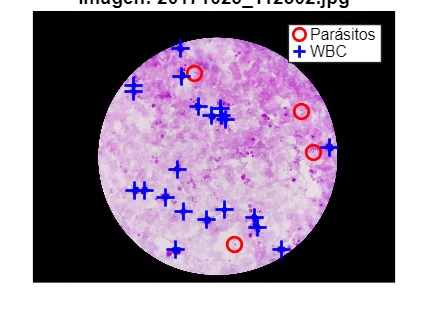

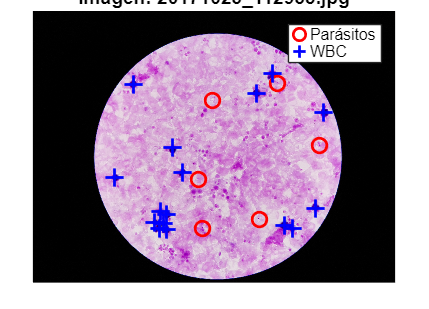

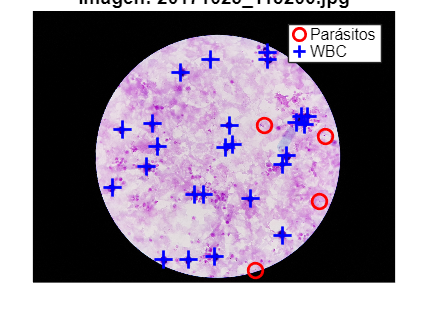

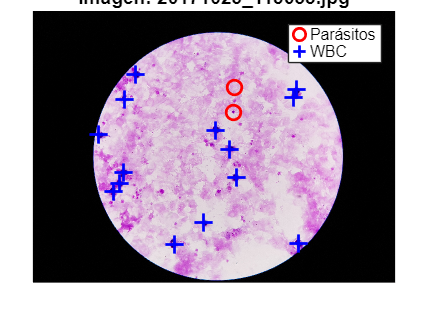

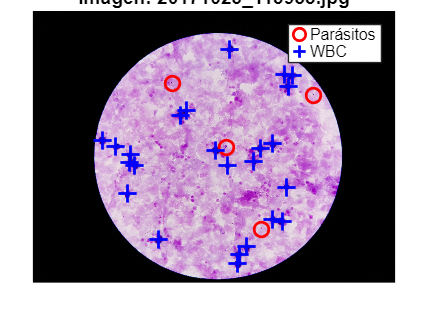

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF1N_1522', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasite'), :);
    if ismember('Var8', datos.Properties.VariableNames) && ismember('Var9', datos.Properties.VariableNames)
    x_parasitos = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    y_parasitos = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    leyenda_parasitos = true;
    else
    disp(['No se encontraron coordenadas de parásitos en la imagen: ', imageFiles(i).name]);
    leyenda_parasitos = false;
    end
    
    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    if leyenda_parasitos
    legend('Parásitos', 'WBC');
    else
    legend('WBC');
    end
    hold off;
end

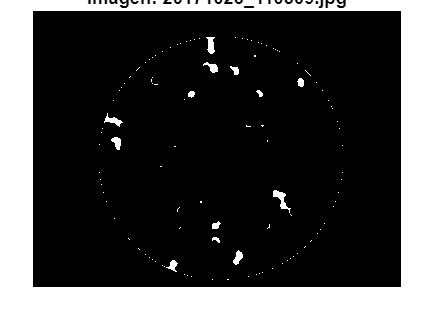

numero_de_wbc = 25

candidatos_a_wbc = 22

wbc_detectados = 11

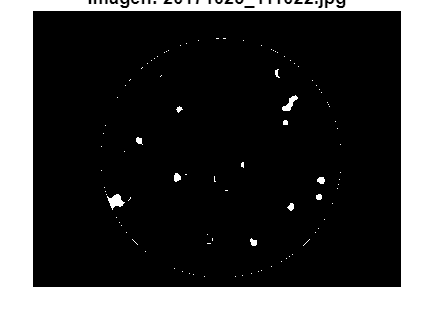

numero_de_wbc = 19

candidatos_a_wbc = 18

wbc_detectados = 12

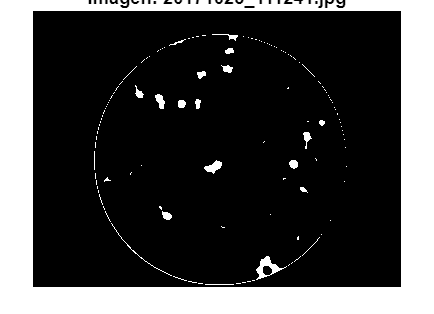

numero_de_wbc = 22

candidatos_a_wbc = 26

wbc_detectados = 12

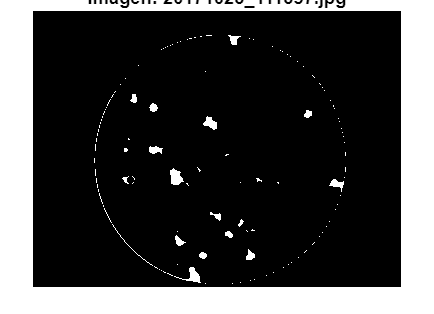

numero_de_wbc = 17

candidatos_a_wbc = 25

wbc_detectados = 12

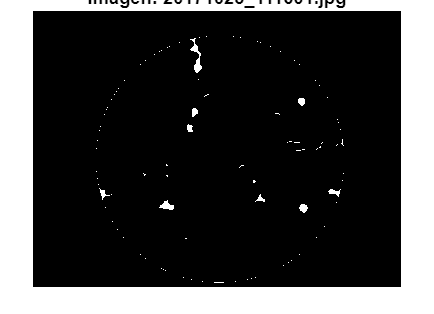

numero_de_wbc = 14

candidatos_a_wbc = 18

wbc_detectados = 7

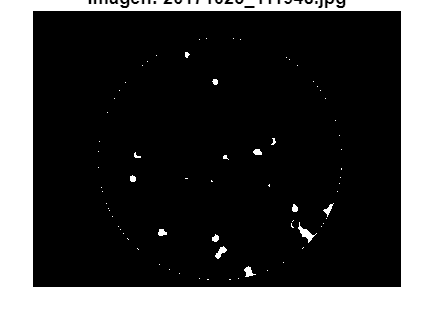

numero_de_wbc = 18

candidatos_a_wbc = 15

wbc_detectados = 11

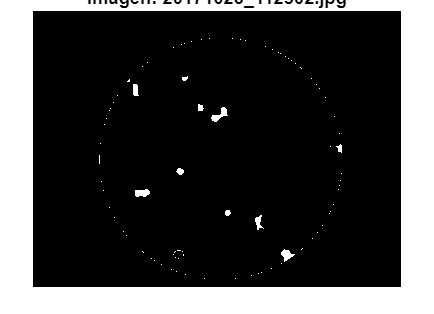

numero_de_wbc = 21

candidatos_a_wbc = 10

wbc_detectados = 8

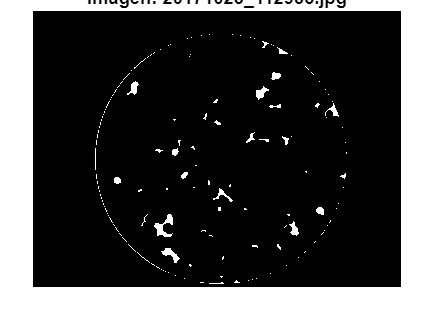

numero_de_wbc = 16

candidatos_a_wbc = 42

wbc_detectados = 9

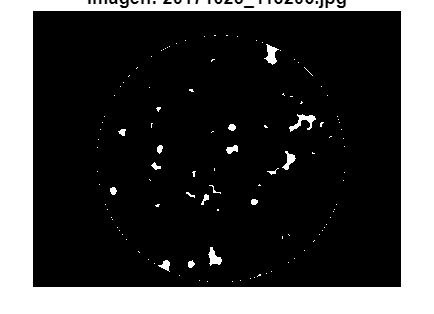

numero_de_wbc = 25

candidatos_a_wbc = 35

wbc_detectados = 15

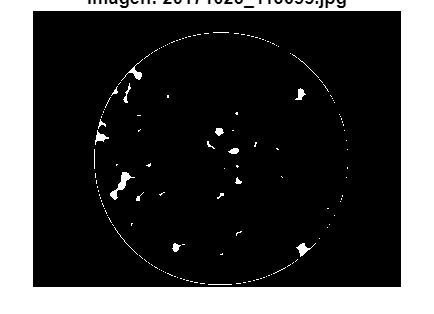

numero_de_wbc = 14

candidatos_a_wbc = 29

wbc_detectados = 6

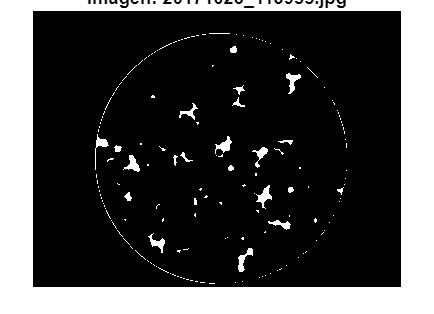

numero_de_wbc = 24

candidatos_a_wbc = 48

wbc_detectados = 9

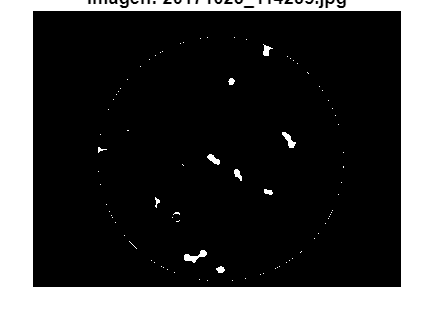

numero_de_wbc = 16

candidatos_a_wbc = 12

wbc_detectados = 8

total_wbc_reales = 0;
total_candidatos = 0;
total_wbc_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
  
    % Pasarlo a escala de grises
    I_gray = rgb2gray(I);

    % Quitar ruido
    I_gray=medfilt2(I_gray, [3 3]);
    
    % Detección de bordes
    BW = edge(I_gray, 'Canny',[0.05 0.4]);
    
    % Cerrar los contornos
    BW = imclose(BW, strel('disk', 40));
    
    % Revisar las propiedades
    CC = bwconncomp(BW,8);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    stats = regionprops(CC,properties);
    
    % Define umbrales de área
    area_min = 200;
    area_max = max([stats.Area]); 
    
    % Crear nueva máscara basada en área
    BW_filtrada_area = false(size(BW));
    labeled_area = labelmatrix(CC);
    
    for a = 1:length(stats)
        area = stats(a).Area;
     
        if area >= area_min && area <= area_max
            BW_filtrada_area = BW_filtrada_area | (labeled_area == a);
        end
    end
    
    % Reemplazar máscara con la filtrada por área
    globulos_blancos = BW_filtrada_area;
    
    %Visualizar
    figure;
    imshow(globulos_blancos,[])
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF1N_1522', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;

    % ============Verificar el modelo========
    
    % Extraer el numero de wbc
    tamano=size(solo_WBC);
    numero_de_wbc = tamano(1,1)
    n=8;
    % Candidatos a wbc
    CC_2 = bwconncomp(globulos_blancos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_wbc=tamano(1,1)

    % wbc detectados
    umbral_distancia = 50;
    wbc_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada wbc real
    for p = 1:length(x_wbc)
        centro_real = [x_wbc(p), y_wbc(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                wbc_detectados = wbc_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un wbc detectado más de una vez
            end
        end
    end
    % Mostrar wbc detectados
    wbc_detectados

    % Sumas de los wbc reales, candidatos y detectados 
    total_wbc_reales = total_wbc_reales + numero_de_wbc;
    total_candidatos = total_candidatos + candidatos_a_wbc;
    total_wbc_detectados = total_wbc_detectados + wbc_detectados;
end


% Analizar modelo con estos resultados
total_wbc_reales

total_wbc_reales = 231

total_candidatos

total_candidatos = 300

total_wbc_detectados

total_wbc_detectados = 120


% Confusion matrix
TP=total_wbc_detectados;
FP=total_candidatos-total_wbc_detectados;
FN=total_wbc_reales-total_wbc_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 51.9481

precision=(TP/(TP+FP))*100

precision = 40

## PARASITOS

### b) 4º Modelo Canny

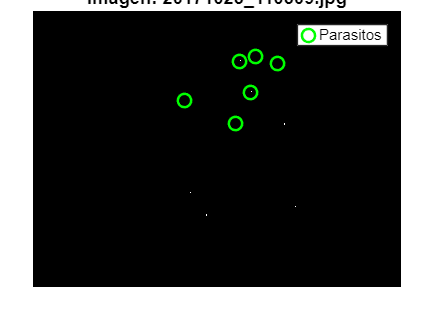

numero_de_parasitos = 6

candidatos_a_parasitos = 8

parasitos_detectados = 4

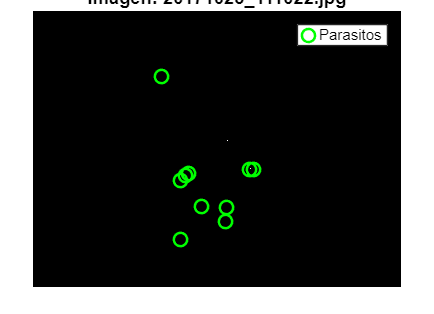

numero_de_parasitos = 10

candidatos_a_parasitos = 3

parasitos_detectados = 2

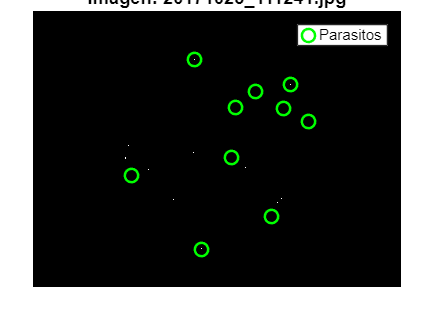

numero_de_parasitos = 10

candidatos_a_parasitos = 17

parasitos_detectados = 5

No se encontraron coordenadas de parásitos en la imagen: 20171023_111357.jpg


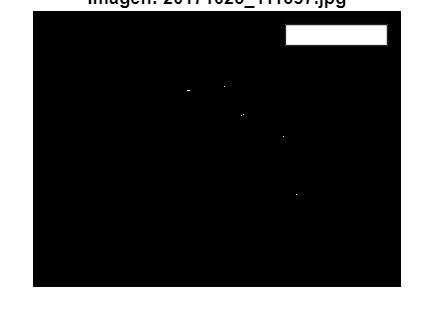

numero_de_parasitos = 0

candidatos_a_parasitos = 10

parasitos_detectados = 0

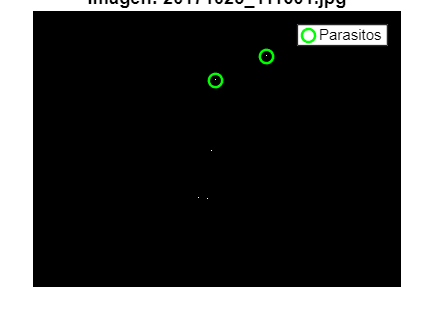

numero_de_parasitos = 2

candidatos_a_parasitos = 11

parasitos_detectados = 2

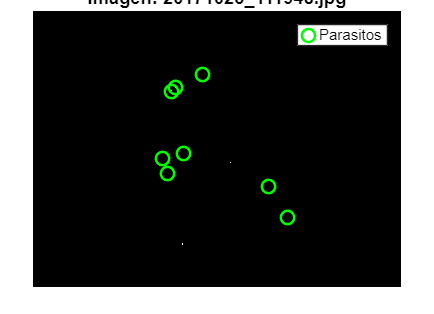

numero_de_parasitos = 8

candidatos_a_parasitos = 9

parasitos_detectados = 5

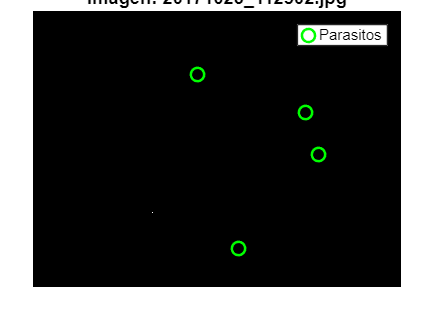

numero_de_parasitos = 4

candidatos_a_parasitos = 2

parasitos_detectados = 1

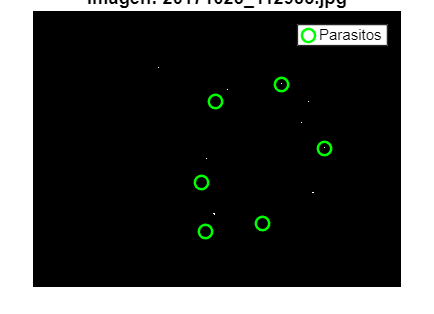

numero_de_parasitos = 6

candidatos_a_parasitos = 16

parasitos_detectados = 4

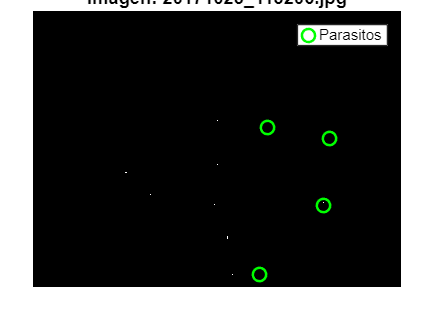

numero_de_parasitos = 4

candidatos_a_parasitos = 12

parasitos_detectados = 1

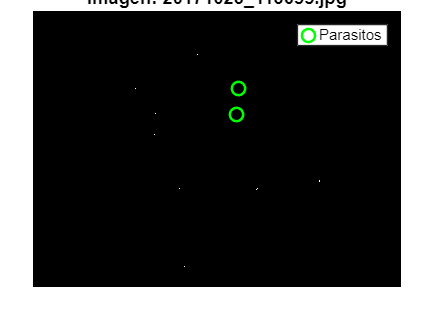

numero_de_parasitos = 2

candidatos_a_parasitos = 21

parasitos_detectados = 1

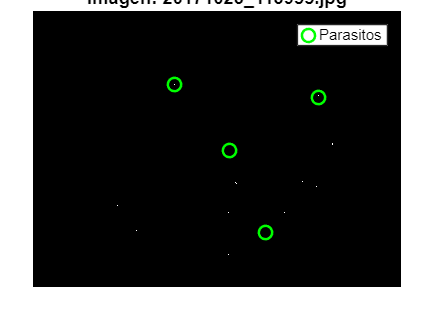

numero_de_parasitos = 4

candidatos_a_parasitos = 21

parasitos_detectados = 2

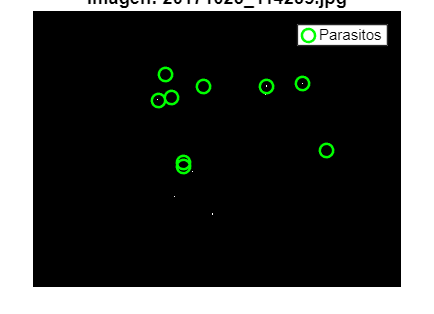

numero_de_parasitos = 9

candidatos_a_parasitos = 10

parasitos_detectados = 3

total_parasitos_reales = 0;
total_candidatos = 0;
total_parasitos_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
  
    % Pasarlo a escala de grises
    I_gray = rgb2gray(I);

    % Quitar ruido
    I_sinruido=medfilt2(I_gray, [3 3]);
    
    % Detección de bordes
    BW = edge(I_sinruido, 'Canny',[0.05 0.4]);
    
    % Cerrar los contornos
    BW = imclose(BW, strel('disk', 40));
    
    % Revisar las propiedades
    CC = bwconncomp(BW,8);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    stats = regionprops(CC,properties);
    
    % Define umbrales de área
    area_min = 200;
    area_max = max([stats.Area]); 
    
    % Crear nueva máscara basada en área
    BW_filtrada_area = false(size(BW));
    labeled_area = labelmatrix(CC);
    
    for c = 1:length(stats)
        area = stats(c).Area;
     
        if area >= area_min && area <= area_max
            BW_filtrada_area = BW_filtrada_area | (labeled_area == c);
        end
    end
    
    % Reemplazar máscara con la filtrada por área
    globulos_blancos = BW_filtrada_area;

    % Mascara de parasitos
    mascara_parasitos=BW-globulos_blancos;

    figure;
    imshow(mascara_parasitos)
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');hold on;

    % % === Detección de círculos (parásitos) ===
    % [centers, radii] = imfindcircles(mascara_parasitos, [1 4], ...
    %     'ObjectPolarity','dark', 'Sensitivity', 0.93, 'EdgeThreshold', 0.1);
    % 
    % % === Mostrar resultados ===
    % figure; imshow(I); hold on;
    % viscircles(centers, radii, 'Color','r');hold on;
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PF\GT_updated\TF1N_1522', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasite'), :);
    if ismember('Var8', datos.Properties.VariableNames) && ismember('Var9', datos.Properties.VariableNames)
    x_parasitos = (solo_parasitos.Var6 + solo_parasitos.Var8) / 2;
    y_parasitos = (solo_parasitos.Var7 + solo_parasitos.Var9) / 2;
    plot(x_parasitos, y_parasitos, 'go', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    leyenda_parasitos = true;
    else
    disp(['No se encontraron coordenadas de parásitos en la imagen: ', imageFiles(i).name]);
    leyenda_parasitos = false;
    end
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    if leyenda_parasitos
    legend('Parasitos');
    else
    legend('No parasitos');
    end
    hold off;

    % ============Verificar el modelo========
    
    % Extraer el numero de parasitos
    tamano=size(solo_parasitos);
    numero_de_parasitos = tamano(1,1)
    n=8;
    % Candidatos a parasitos
    CC_2 = bwconncomp(mascara_parasitos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_parasitos=tamano(1,1)

    % Parasitos detectados
    umbral_distancia = 50;
    parasitos_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada parásito real
    for p = 1:length(x_parasitos)
        centro_real = [x_parasitos(p), y_parasitos(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                parasitos_detectados = parasitos_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un parásito detectado más de una vez
            end
        end
    end
    % Mostrar parasitos detectados
    parasitos_detectados

    % Sumas de los parasitos reales, candidatos y detectados 
    total_parasitos_reales = total_parasitos_reales + numero_de_parasitos;
    total_candidatos = total_candidatos + candidatos_a_parasitos;
    total_parasitos_detectados = total_parasitos_detectados + parasitos_detectados;
end


% Ananlizar modelo con estos resultados
total_parasitos_reales

total_parasitos_reales = 65

total_candidatos

total_candidatos = 140

total_parasitos_detectados

total_parasitos_detectados = 30


% Confusion matrix
TP=total_parasitos_detectados;
FP=total_candidatos-total_parasitos_detectados;
FN=total_parasitos_reales-total_parasitos_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 46.1538

precision=(TP/(TP+FP))*100

precision = 21.4286